% EEGLAB history file generated on the 21-Sep-2024
% ------------------------------------------------

EEG.etc.eeglabvers = '2024.2'; % this tracks which version of EEGLAB is being used, you may ignore it

% rootPath = 'D:\WorkSpace\MyDataSets\BCICIV_2a_216\LRP';
rootPath = 'D:\WorkSpace\MyDataSets\BCICIV_2a_216\CZC';
savefolderPath = 'D:\WorkSpace\SelfDataSet\BCICIV_2a_mat_216\'

savefolderPath = 'D:\WorkSpace\SelfDataSet\BCICIV_2a_mat_216\'

Daypath = 'D2\';
fileInfo = dir(fullfile(rootPath, Daypath,'run*_Raw_Data.mat'));
disp(fileInfo)

  包含以下字段的 6×1 struct 数组:

    name
    folder
    date
    bytes
    isdir
    datenum




% 提取文件名
fileNames = {fileInfo.name};

filesPath = {};
for sub = 1:length(fileNames)
    filesPath{sub} = fullfile(rootPath, Daypath, fileNames{sub});
end

EEG = pop_loadbva(filesPath{1});

Importing data
Importing channel location information
Importing events
eeg_checkset note: creating the original event table (EEG.urevent)


EEG=pop_chanedit(EEG, 'changefield',{64,'labels','FCz'}); % 将lz通道改名为FCz
EEG=pop_chanedit(EEG, 'changefield',{64,'theta','0'},'changefield',{64,'radius','0.17222'},'changefield',{64,'X','0.37049'},'changefield',{64,'Y','0'},'changefield',{64,'Z','0.85717'},'changefield',{64,'sph_phi','59'},'changefield',{64,'sph_theta','0'},'changefield',{64,'radius','0.125'}); % 更改FCz坐标
% EEG = pop_select( EEG,'channel',{'FC1','Fz','C3','CP1','Pz','CP2','Cz','C4','FC2','FC3','C1','C5','CP3','P1','POz','P2','CPz','CP4','C6','C2','FC4','Iz'});
%  更改不能改变顺序

EEG = pop_select( EEG, 'channel',{'Fz','FC1','C3','CP1','Pz','CP2','Cz','C4','FC2','FC3','C1','C5','CP3','P1','POz','P2','CPz','CP4','C6','C2','FC4','FCz','FC5','FC6','FCz'}); % 只保留需要的2a数据集的21个EEG通道没有FCz使用FC5和FC6插值并存入原Oz中,一共24个通道

Removing 43 channel(s)...


if EEG.srate ~= 250
    EEG = pop_resample( EEG, 250); % 降采样到250/sec
    disp('采样率更改为250/sec')
else
    disp('采样率为250/sec')
end

采样率为250/sec


pop_eegfiltnew() - performing 1651 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.5 Hz
pop_eegfiltnew() - passband edge(s): [0.5 32] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.25 32.25] Hz


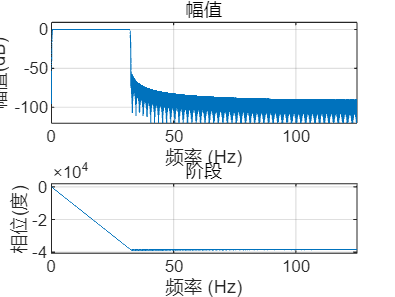

pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


EEG = pop_eegfiltnew(EEG, 'locutoff',0.5,'hicutoff',32,'plotfreqz',1); % 带通滤波的频带为(0.5~32)

% 从EEG结构体中提取 'data', 'event', 'chanlocs'等字段
eegdata_Raw = EEG.data;
event_Raw = EEG.event;
originalchs = EEG.chanlocs;

Raw_label_order = {originalchs.labels}

Raw_label_order = 1×24 cell 数组
    {'C3'}    {'C4'}    {'Fz'}    {'Cz'}    {'Pz'}    {'FC1'}    {'FC2'}    {'CP1'}    {'CP2'}    {'FC5'}    {'FC6'}    {'C1'}    {'C2'}    {'P1'}    {'P2'}    {'FC3'}    {'FC4'}    {'CP3'}    {'CP4'}    {'C5'}    {'C6'}    {'CPz'}    {'POz'}    {'FCz'}


% target_order = {'Fz','FC3','FC1','FCz','FC2','FC4','C5','C3','C1','Cz','C2','C4','C6','CP3','CP1','CPz','CP2','CP4','P1','Pz','P2','POz','FC5','FC6'}; % FC5,FC6用于插值FCz
% 
% % 获取对应的序号
% traget_label_indices = zeros(length(Raw_label_order), 1);
% for i = 1:length(Raw_label_order)
%     index = find(strcmp(target_order, Raw_label_order{i}));
%     traget_label_indices(i) = index;
% end
% fc5_index = indices(strcmp('FC5', target_order));
% fc6_index = indices(strcmp('FC6', target_order));
% fcz_index = indices(strcmp('FCz', target_order));
% eegdata_Raw(:, fcz_index, :) = (eegdata_Raw(:, fc5_index, :) + eegdata_Raw(:, fc6_index, :))/2
% % 重新排列数组
% rearrangedData = eegdata_Raw(:, traget_label_indices, :);
% 
% % 显示重新排列后的数组大小，确认操作成功
% disp(size(rearrangedData));

% FC5,FC6用于插值FCz
target_order = {'Fz','FC3','FC1','FCz','FC2','FC4','C5','C3','C1','Cz','C2','C4','C6','CP3','CP1','CPz','CP2','CP4','P1','Pz','P2','POz','FC5','FC6'}; 

% 获取对应的序号
target_label_indices = zeros(length(target_order), 1); % 注意变量名的一致性
for i = 1:length(target_order)
    index = find(strcmp(Raw_label_order, target_order{i}));
    if ~isempty(index) % 确保找到了索引
        target_label_indices(i) = index(1); % 使用找到的第一个索引
    else
        target_label_indices(i) = NaN; % 如果找不到，赋值为NaN或其他标记值
    end
end

% 获取特定电极的索引
fc5_index = find(strcmp(Raw_label_order, 'FC5'));
fc6_index = find(strcmp(Raw_label_order, 'FC6'));
fcz_index = find(strcmp(Raw_label_order, 'FCz'));

% 计算 FCz 的数据
if ~isnan(fcz_index) && ~isnan(fc5_index) && ~isnan(fc6_index)
    eegdata_Raw(fcz_index, :) = (eegdata_Raw(fc5_index, :) + eegdata_Raw(fc6_index, :)) / 2;
end
target_label_indices = target_label_indices(1:end-2)

target_label_indices =      3
    16
     6
    24
     7
    17
    20
     1
    12
     4


% 重新排列数组
rearrangedData = eegdata_Raw(target_label_indices, :);
% rearrangedData = eegdata_Raw(target_label_indices, :);

% 显示重新排列后的数组大小，确认操作成功
disp(size(rearrangedData));

          22      106555



% 定义要筛选的标签及其对应的数字
type_map = containers.Map({'S 10', 'S 20', 'S 30', 'S 40'}, [1, 2, 3, 4]);

% 筛选出包含特定标签的结构体元素
selected_tags = {'S 10', 'S 20', 'S 30', 'S 40'};
filtered_events = event_Raw(ismember({event_Raw.type}, selected_tags));

% 为筛选后的结构体数组添加新字段 'label' 并赋值
for i = 1:length(filtered_events)
    if type_map.isKey(filtered_events(i).type)
        filtered_events(i).label = type_map(filtered_events(i).type);
    else
        filtered_events(i).label = NaN; % 如果没有匹配的类型，可以赋值为 NaN 或其他适当的值
    end
    % 对 'latency' 字段数据进行取整
    filtered_events(i).latency = round(filtered_events(i).latency);
end

% 创建一个新的结构体数组 event_tmp，只包含 label 和 latency 字段
event = struct('label', {}, 'latency', {});

% 遍历 filtered_events，将 label 和 latency 字段的值赋给 event_tmp
for i = 1:length(filtered_events)
    event(i).label = filtered_events(i).label;
    event(i).latency = filtered_events(i).latency;
end

% 显示筛选、添加新字段并取整后的结构体数组
disp(event);

  包含以下字段的 1×48 struct 数组:

    label
    latency



event_duration = 1000; % 样本数,本代码共保存1000/250=4s的数据

data = {};
indicesToKeep = {};

% 初始化 data 和 eeglabel_tmp
j = 1;
num_events = length(event); % 假设 event 是一个结构体数组
max_duration = size(rearrangedData, 2); % 假设 eegdata_Raw 是一个 2D 矩阵
data_tmp = zeros(num_events, size(rearrangedData, 1), event_duration); % 预分配空间
eeglabel_tmp = zeros(num_events, 1); % 预分配空间

for i = 1:num_events
    if any(event(i).label == [1, 2, 3, 4])
        % 确保不会超出 eegdata_Raw 的边界
        start_idx = event(i).latency;
        end_idx = min(start_idx + event_duration - 1, max_duration);
        
        % 提取数据片段
        data_tmp(j, :, 1:end_idx - start_idx + 1) = rearrangedData(:, start_idx:end_idx);
        
        % 存储标签
        eeglabel_tmp(j) = event(i).label;
        
        % 更新索引
        j = j + 1;
    end
end

% 移除未使用的空间（如果有必要）
data_tmp = data_tmp(1:j-1, :, :);
eeglabel_tmp = eeglabel_tmp(1:j-1);

% % 显示结果
% disp(data_tmp);
% disp(eeglabel_tmp);